% Rocky_5_closed_loop_poles.m
%
% 1) Symbolically calculates closed loop transfer function of PI disturbannce
% rejection control system for Rocky. 
% No motor model (M =1). With motor model (1st order TF)
%
% 2) Specify location of (target)poles based on desired reponse. The number of
% poles = denominator polynomial of closed loop TF
%
% 3) Extract the closed loop denomiator poly and set = polynomial of target
% poles
%
% 4) Solve for Ki, Kp, Ji, Jp, Ci to match coefficients of polynomials. In general,
% this will be underdefined and will not be able to place poles in exact
% locations. In this case (5th order), the control constants can be found exactly 
%
% 5) Plot impulse response to see closed-loop behavior. 
%
% based on code by SG. last modified 3/8/22 CL

clear all; 
close all;

syms s a b l g Kp Ki Jp Ji Ci   % define symbolic variables

Hvtheta = -s/l/(s^2-g/l);       % TF from velocity to angle of pendulum

K = Kp + Ki/s;                  % TF of the PI angle controller
M = a*b/(s+a);                  % TF of motor (1st order model) 
% M = 1;                        % TF without motor
%
J = Jp + Ji/s + Ci/s^2;         % TF of controller around motor-combined PI of x and v
Mfb = M/(1+M*J);                % Black's formula to get tf for motor with PI feedback control 

%  
% closed loop transfer function from disturbance d(t)totheta(t)
% Hcloop = 1/(1-Hvtheta*M*K)    % use this for no motor feedback
% with motor feedback

Hcloop = 1/(1-Hvtheta*Mfb*K)    % use this for motor with feedback

$$Hcloop = -\frac{1}{\frac{a\,b\,s\,\left(\mathrm{Kp}+\frac{\mathrm{Ki}}{s}\right)}{l\,\left(\frac{g}{l}-s^{2}\right)\,\left(a+s\right)\,\left(\frac{a\,b\,\left(\mathrm{Jp}+\frac{\text{Ci}}{s^{2}}+\frac{\mathrm{Ji}}{s}\right)}{a+s}+1\right)}-1}$$


pretty(simplify(Hcloop))       % to display the total transfer function

                                1
- ------------------------------------------------------------
                          2
                     a b s  (Ki + Kp s)
  -------------------------------------------------------- - 1
        2          2    3                    2
  (- l s  + g) (a s  + s  + Ci a b + Jp a b s  + Ji a b s)




% Substitute parameters and solve
% system parameters
g = 9.81;
l = 0.4865;  %effective length 
a = 18;           %nominal motor parameters
b = 0.3;        %nominal motor parameters

Hcloop_sub = subs(Hcloop) % sub parameter values into Hcloop

$$Hcloop\_sub = \frac{1}{\frac{10800\,s\,\left(\mathrm{Kp}+\frac{\mathrm{Ki}}{s}\right)}{973\,\left(s^{2}-\frac{19620}{973}\right)\,\left(\frac{27\,\left(\mathrm{Jp}+\frac{\text{Ci}}{s^{2}}+\frac{\mathrm{Ji}}{s}\right)}{5\,\left(s+18\right)}+1\right)\,\left(s+18\right)}+1}$$


% specify locations of the target poles,
% choose # based on order of Htot denominator
% e.g., want some oscillations, want fast decay, etc. 

% p1 = -1 + 2*pi*i    % dominant pole pair
% p2 = -1 - 2*pi*i    % dominant pole pair 
% p3 = -10
% p4 = -8
% p5 = -8.

p1 = -5.4+2.62*1i  % dominant pole pair

p1 = -5.4000 + 2.6200i

p2 = -5.4-2.62*1i    % dominant pole pair 

p2 = -5.4000 - 2.6200i

p3 = -5.1+3.161*1i

p3 = -5.1000 + 3.1610i

p4 = -5.1-3.161*1i   % dominant pole pair

p4 = -5.1000 - 3.1610i

p5 = -6     % dominant pole pair 

p5 = -6


% target characteristic polynomial
% if motor model (TF) is added, order of polynomial will increases
% tgt_char_poly = (s-p1)*(s-p2)*(s-p3)

% check polynomial-expand to fifth order 
tgt_char_poly = (s-p1)*(s-p2)*(s-p3)*(s-p4)*(s-p5)

$$tgt\_char\_poly = \left(s+6\right)\,\left(s+\frac{27}{5}-\frac{131}{50}\,\mathrm{i}\right)\,\left(s+\frac{27}{5}+\frac{131}{50}\,\mathrm{i}\right)\,\left(s+\frac{51}{10}-\frac{3161}{1000}\,\mathrm{i}\right)\,\left(s+\frac{51}{10}+\frac{3161}{1000}\,\mathrm{i}\right)$$

exp_tgt_char_poly = expand(tgt_char_poly)

$$exp\_tgt\_char\_poly = s^{5}+27\,s^{4}+\frac{308186321\,s^{3}}{1000000}+\frac{2311734441\,s^{2}}{1250000}+\frac{14586413409181\,s}{2500000000}+\frac{9727107021543}{1250000000}$$


% get the denominator from Hcloop_sub
[n d] = numden(Hcloop_sub)

$$n = \left(973\,s^{2}-19620\right)\,\left(27\,\text{Ci}+27\,\mathrm{Ji}\,s+27\,\mathrm{Jp}\,s^{2}+90\,s^{2}+5\,s^{3}\right)$$

$$d = 26271\,\text{Ci}\,s^{2}-529740\,\mathrm{Ji}\,s-529740\,\text{Ci}+26271\,\mathrm{Ji}\,s^{3}-529740\,\mathrm{Jp}\,s^{2}+26271\,\mathrm{Jp}\,s^{4}+54000\,\mathrm{Ki}\,s^{2}+54000\,\mathrm{Kp}\,s^{3}-1765800\,s^{2}-98100\,s^{3}+87570\,s^{4}+4865\,s^{5}$$


% find the coefficients of the denominator polynomial TF
coeffs_denom = coeffs(d, s)

$$coeffs\_denom = \left(\begin{array}{cccccc} -529740\,\text{Ci} & -529740\,\mathrm{Ji} & 26271\,\text{Ci}-529740\,\mathrm{Jp}+54000\,\mathrm{Ki}-1765800 & 26271\,\mathrm{Ji}+54000\,\mathrm{Kp}-98100 & 26271\,\mathrm{Jp}+87570 & 4865 \end{array}\right)$$


% divide though the coefficient of the highest power term
coeffs_denom = coeffs(d, s)/(coeffs_denom(end))

$$coeffs\_denom = \left(\begin{array}{cccccc} -\frac{105948\,\text{Ci}}{973} & -\frac{105948\,\mathrm{Ji}}{973} & \frac{27\,\text{Ci}}{5}-\frac{105948\,\mathrm{Jp}}{973}+\frac{10800\,\mathrm{Ki}}{973}-\frac{353160}{973} & \frac{27\,\mathrm{Ji}}{5}+\frac{10800\,\mathrm{Kp}}{973}-\frac{19620}{973} & \frac{27\,\mathrm{Jp}}{5}+18 & 1 \end{array}\right)$$

% num_coeff_denom = length(coeffs_denom)

% find coefficients of the target charecteristic polynomial
coeffs_tgt = coeffs(tgt_char_poly, s)

$$coeffs\_tgt = \left(\begin{array}{cccccc} \frac{9727107021543}{1250000000} & \frac{14586413409181}{2500000000} & \frac{2311734441}{1250000} & \frac{308186321}{1000000} & 27 & 1 \end{array}\right)$$

% num_coeff_tgt = length(coeffs_tgt)

% for check. reorder the coefficients to match the denomimator polynomial
for ii = 1:length(coeffs_denom)
    reord_coeffs_tgt(ii) = coeffs_tgt(length(coeffs_tgt) + 1 - ii);
end
% check roots of target polynomial-should be same as selected poles
roots_target = vpa(roots(reord_coeffs_tgt),4)

$$roots\_target = \left(\begin{array}{c} -6.0\\ -5.4-2.62\,\mathrm{i}\\ -5.4+2.62\,\mathrm{i}\\ -5.1-3.161\,\mathrm{i}\\ -5.1+3.161\,\mathrm{i} \end{array}\right)$$



% solve the system of equations setting the coefficients of the
% polynomial in the target to the actual polynomials
solutions = solve(coeffs_denom(1:5) == coeffs_tgt(1:5), Jp, Ji,  Kp, Ki, Ci);

% display the solutions as double precision numbers
Kp = double(solutions.Kp)

Kp = 55.6502

Ki = double(solutions.Ki)

Ki = 250.4339

Ji = double(solutions.Ji)

Ji = -53.5832

Jp = double(solutions.Jp)

Jp = 1.6667

Ci = double(solutions.Ci)

Ci = -71.4651


%write out denominator polynomial 
aaa = vpa(subs(coeffs_denom),4)

$$aaa = \left(\begin{array}{cccccc} 7782.0 & 5835.0 & 1849.0 & 308.2 & 27.0 & 1.0 \end{array}\right)$$


% reorder coefficients for the check polynomial 
for ii = 1:length(coeffs_denom)
    chk_coeffs_denom(ii) = coeffs_denom(length(coeffs_denom) + 1 - ii);
end

% check poles should be same as chosen input poles 
check_closed_loop_poles = vpa (roots(subs(chk_coeffs_denom)), 4)

$$check\_closed\_loop\_poles = \left(\begin{array}{c} -6.0\\ -5.1-3.161\,\mathrm{i}\\ -5.1+3.161\,\mathrm{i}\\ -5.4+2.62\,\mathrm{i}\\ -5.4-2.62\,\mathrm{i} \end{array}\right)$$


% write out target polynomial 
% bbb = vpa( expand( (s-check_closed_loop_poles(1))*(s-check_closed_loop_poles(2)) ...
%     *(s-check_closed_loop_poles(3))*(s-check_closed_loop_poles(4)) ...
%     *(s-check_closed_loop_poles(5)) ) )



% Plot impulse and step responses of closed-loop system
    TFstring = char(subs(Hcloop));
    % Define 's' as transfer function variable
    s = tf('s');
    % Evaluate the expression
    eval(['TFH = ',TFstring]);

TFH =
 
  2.119e44 s^8 + 9.536e45 s^7 + 3.74e46 s^6 - 1.378e48 s^5 - 2.312e48 s^4 + 2.39e49 s^3 + 2.968e49 s^2
  ----------------------------------------------------------------------------------------------------
  2.119e44 s^8 + 9.536e45 s^7 + 1.683e47 s^6 + 1.567e48 s^5 + 8.29e48 s^4 + 2.39e49 s^3 + 2.968e49 s^2
 
Continuous-time transfer function.



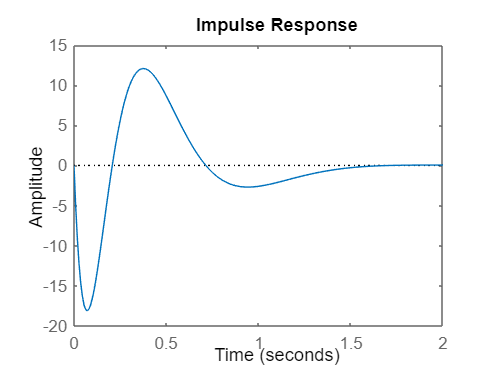

    figure (1)
    impulse(TFH);   %plot the impulse reponse

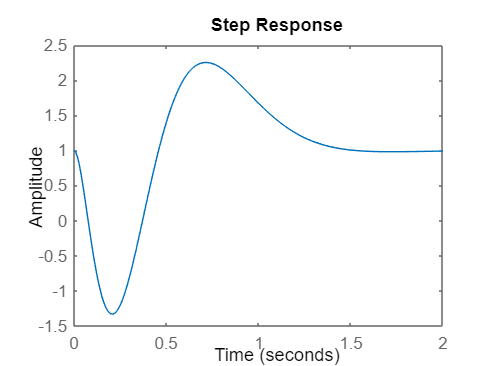

    figure(2)
    step(TFH)       %plot the step response